**Jan 29, 2020 Interative Matlab Bsic Operation 2**

**Name:** Jikhan Jeong

**Ref: **Essential Matlab for Engineers and Scientists

- How to handline *.m function inline, out of interactive note , and inside interactive note

- If we want to use a function commend inside of interactive note, using in with inline method or put it in the end of incerative note (recommend to save out of interative as a *.m, because the note cannot break down in in. 

**Inline Function**

h = inline('cos(8*x) + cos(9*x)')


h =

     Inline function:
     h(x) = cos(8*x) + cos(9*x)



x = 0: pi/40 : 6*pi

x =          0    0.0785    0.1571    0.2356    0.3142    0.3927    0.4712    0.5498    0.6283    0.7069    0.7854    0.8639    0.9425    1.0210    1.0996    1.1781    1.2566    1.3352    1.4137    1.4923    1.5708    1.6493    1.7279    1.8064    1.8850    1.9635    2.0420    2.1206    2.1991    2.2777    2.3562    2.4347    2.5133    2.5918    2.6704    2.7489    2.8274    2.9060    2.9845    3.0631    3.1416    3.2201    3.2987    3.3772    3.4558    3.5343    3.6128    3.6914    3.7699    3.8485


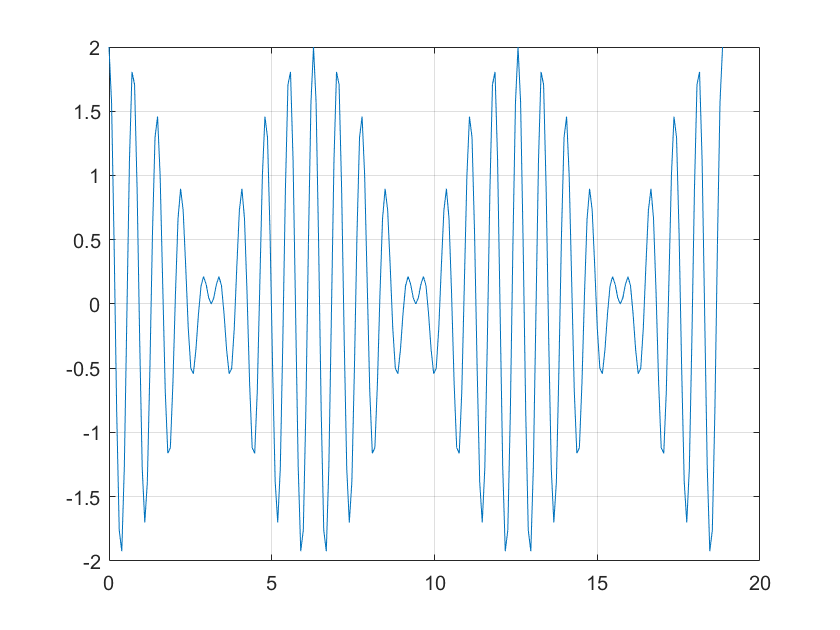

plot(x, h(x)), grid

f = inline('x.^2 + y.^2','x','y');

f(1,2)

ans = 5

**Matrix Operation**

a = [1 2; 3 4];
b = [5 6; 7 8];

c = a*b

c =     19    22
    43    50


d = a.*b % element wise manipulation

d =      5    12
    21    32


a^2

ans =      7    10
    15    22


disp('determinat')

determinat


det(a)

ans = -2

disp('eigenvalue decomposition')

eigenvalue decomposition


eig(a)

ans =    -0.3723
    5.3723


disp('inverse')

inverse


inv(a)

ans =    -2.0000    1.0000
    1.5000   -0.5000


disp('LU factorization')

LU factorization


lu(a)

ans =     3.0000    4.0000
    0.3333    0.6667


disp('orthogonal factorization')

orthogonal factorization


qr(a)

ans =    -3.1623   -4.4272
    0.7208   -0.6325


disp('singular value decomposition')

singular value decomposition


svd(a)

ans =     5.4650
    0.3660


disp('null space')

null space


A=[1 1 2;
    2 1 3;
    3 1 4;
    4 1 5;]

A =      1     1     2
     2     1     3
     3     1     4
     4     1     5


nu=null(A) % Null space

nu =     0.5774
    0.5774
   -0.5774


**While Loop**

matnum = floor(10*rand + 1)

matnum = 10


fn2 =

     Inline function:
     fn2(x) = x^3 + x -3




dfn2 =

     Inline function:
     dfn2(x) = 3*x^2+1



steps =0;
re = 1e-8;
myrel =1;
x = input('Initial guess:'); % input turn out in command line , not in this notebook
disp(x)

    10



% need to call x input
while myrel > re & (steps <20)
    xold = x
    x = x - f(x)/df(x); % function in out of interactive cell as .m files 
    steps = steps +1;
    disp([x fn(x)])
    myrel = abs((x-xold)/x)
end
% need to run x inputend

xold = 10

    6.6545  298.3295



myrel = 0.5027

xold = 6.6545

    4.4256   88.1047



myrel = 0.5036

xold = 4.4256

    2.9512   25.6556



myrel = 0.4996

xold = 2.9512

    2.0055    7.0722



myrel = 0.4715

xold = 2.0055

    1.4643    1.6040



myrel = 0.3696

xold = 1.4643

    1.2485    0.1945



myrel = 0.1729

xold = 1.2485

    1.2142    0.0044



myrel = 0.0282

xold = 1.2142

    1.2134    0.0000



myrel = 6.6248e-04

xold = 1.2134

    1.2134    0.0000



myrel = 3.5802e-07

xold = 1.2134

    1.2134   -0.0000



myrel = 1.0449e-13

% need to call x input
while myrel > re & (steps <20)
    xold = x
    x = x - fn(x)/dfn(x); % function in the end
    steps = steps +1;
    disp([x fn(x)])
    myrel = abs((x-xold)/x)
end

xold = 10

    6.6545  298.3295



myrel = 0.5027

xold = 6.6545

    4.4256   88.1047



myrel = 0.5036

xold = 4.4256

    2.9512   25.6556



myrel = 0.4996

xold = 2.9512

    2.0055    7.0722



myrel = 0.4715

xold = 2.0055

    1.4643    1.6040



myrel = 0.3696

xold = 1.4643

    1.2485    0.1945



myrel = 0.1729

xold = 1.2485

    1.2142    0.0044



myrel = 0.0282

xold = 1.2142

    1.2134    0.0000



myrel = 6.6248e-04

xold = 1.2134

    1.2134    0.0000



myrel = 3.5802e-07

xold = 1.2134

    1.2134   -0.0000



myrel = 1.0449e-13

fn2 = inline('x^3 + x -3')


fn2 =

     Inline function:
     fn2(x) = x^3 + x -3



dfn2 = inline('3*x^2+1')


dfn2 =

     Inline function:
     dfn2(x) = 3*x^2+1



% need to run x input
while myrel > re & (steps <20)
    xold = x
    x = x - fn2(x)/dfn2(x); % function inline
    steps = steps +1;
    disp([x fn(x)])
    myrel = abs((x-xold)/x)
end

xold = 10

    6.6545  298.3295



myrel = 0.5027

xold = 6.6545

    4.4256   88.1047



myrel = 0.5036

xold = 4.4256

    2.9512   25.6556



myrel = 0.4996

xold = 2.9512

    2.0055    7.0722



myrel = 0.4715

xold = 2.0055

    1.4643    1.6040



myrel = 0.3696

xold = 1.4643

    1.2485    0.1945



myrel = 0.1729

xold = 1.2485

    1.2142    0.0044



myrel = 0.0282

xold = 1.2142

    1.2134    0.0000



myrel = 6.6248e-04

xold = 1.2134

    1.2134    0.0000



myrel = 3.5802e-07

xold = 1.2134

    1.2134   -0.0000



myrel = 1.0449e-13

if myrel <= re
    disp('zero found at')
    disp(x)
else
    disp('zero not found')
end;

zero found at


    1.2134



f(10) % call from f.m

ans = 1007

df(10) % call from df.m

ans = 301